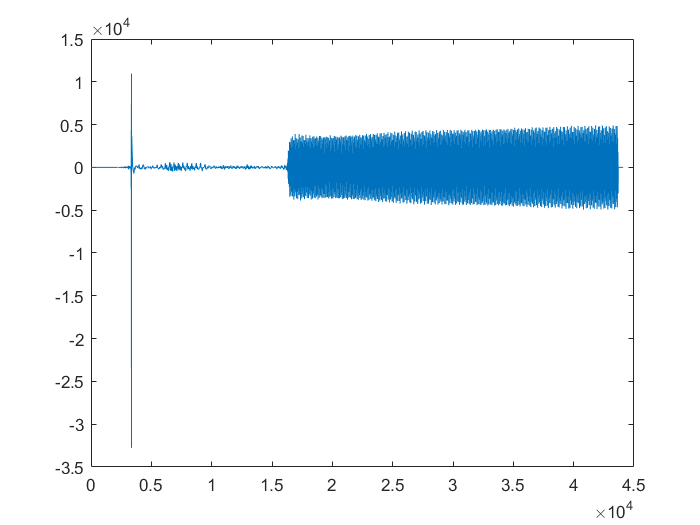

fs=44100;
signal=importdata("stream.txt");
for i=43687:44100
    signal(1,i)=0;
end


plot(signal);

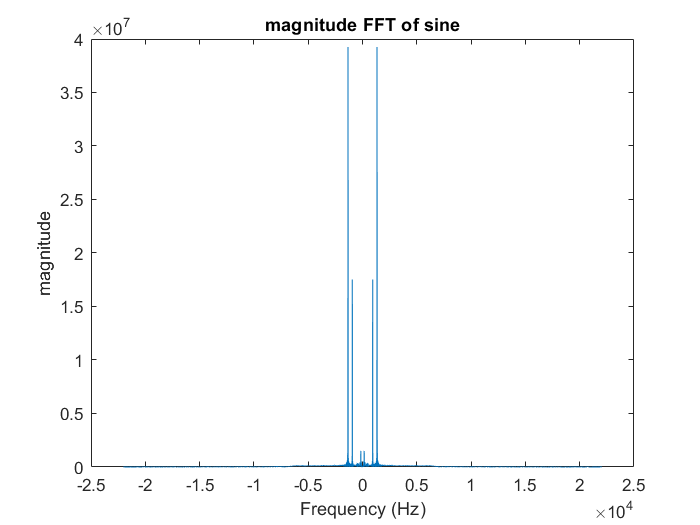

fftSignal = fft(signal);
fftSignal = fftshift(fftSignal);
f = fs/2*linspace(-1,1,fs);
figure;
plot(f, abs(fftSignal));
d=abs(fftSignal);
title('magnitude FFT of sine');
xlabel('Frequency (Hz)');
ylabel('magnitude');

[val,idx]=max(d);